clear
close all
hold off

%Vamos a representar cómo se mueve el centro de la formación

N=5; %Número de robots, uno adicional en el centro de la formación
iteration=500; %Número de iteraciones
step_size=0.1;
D=1; %Radio de la formación
S=10^-4*[2,1;1,1]; %Matriz
c0=[20;20]; %Posición del centro inicial (initial guess)
r0=[0 0]'; %Centro de contaminación
e=[1;0];
w0=1; %Movimiento circular de un radián por segundo
a=0.01; %parámetro para controlar la Hessiana
c1=10^-4;
c2=0.9; %Parámetros para el line search (c2=0.7 da solución rápida, valores más bajos resultan en un tiempo de computación notable)
k=1.1; %Valor para el line search inexacto

colors=["ob","ok","or","om","og"];
tf=20;
t=linspace(0,tf,iteration);
%Condiciones iniciales
c(:,1)=c0;
plot(c0(1,1),c0(2,1),'ob')
hold on
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
mod_rc=mod_r_c(1);
pos_rob=zeros(2,N,iteration);
i=1;

while mod_rc>0.001
    K=0;
    grad_sum=0;
    if iteration==i
        break
    end
    for j=1:N
        %A este ángulo se le puede añadir movimiento rotatorio (w*t)
        phi=w0*t(i)+2*pi()*j/N;
        R=[cos(phi) -sin(phi);sin(phi) cos(phi)];
        %Posición del robot individual
        pos_rob(:,j,i)=c0+D*R*e;
        r_i=pos_rob(:,j,i);
        %Suma para la K
        K=K+(100*exp(-r_i'*S*r_i)-100*exp(-c0'*S*c0))*(r_i-c0)*(r_i-c0)';
    end
    %Aproximación de la K en el centro
    K_centr=16/(N*D^4)*K;
    %Aproximación del Hessiano, solución de la ecuación general:
    H12=K_centr(2,1)/2;
    A=[3 1;1 3];
    b=[K_centr(1,1);K_centr(2,2)];
    vec_x=linsolve(A,b);
    H11=vec_x(1,1);
    H22=vec_x(2,1);
    H=[H11 H12;H12 H22];
    grad_centr(:,i)=gradiente_2D_positivo(c(:,i),t(i),N,D,S,w0);
    %En caso de que el Hessiano no esté bien condicionado, se invierte la
    %matriz identidad

    if (all(eig(H) > 0) || cond(H)>1/a)
        H_inv=inv(eye(2));
    else
        H_inv=H^-1;
    end
    alpha1=1; 
    p(:,i)=-H_inv*grad_centr(:,i); %Dirección descendente
    steplengthParam=[c1,c2,alpha1,k];
    [alpha(i),u(i)]=alpha_strongWolfe(c(:,i), p(:,i), steplengthParam,t(i),N,D,S,w0); 
    %Aplicación de la aproximación por el Hessiano
    c(:,i+1)=c0-alpha(:,i)*H_inv*grad_centr(:,i);
    if norm(c(:,i+1)-r0)>mod_r_c(i)
        c(:,i+1)=c0+step_size*grad_centr(:,i);
        i
    end
        %Hay un nuevo centro alrededor del cual se tienen que poner los robots
    c0=c(:,i+1);
        %Sacar el módulo de la diferencia entre el centro y el punto de
        %contaminación para cada iteración
    mod_r_c(i+1)=norm(c0-r0);
    mod_rc=mod_r_c(i+1);
    i=i+1;
end

Representación del centro:

plot(c(1,:),c(2,:),'r')
hold on

Representación de los robots:

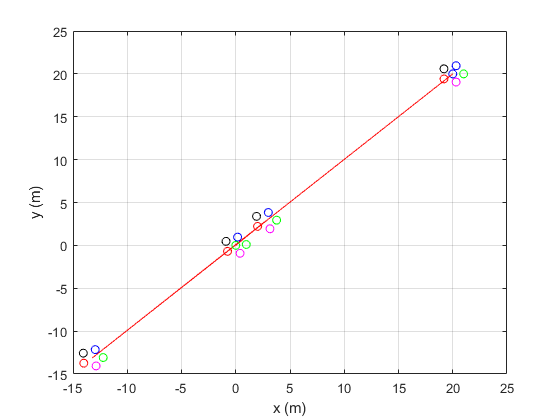

for g=1:N
    for z=1:iteration
        plot(pos_rob(1,g,z),pos_rob(2,g,z),colors(g))
        hold on
    end
end
xlabel('x (m)')
ylabel('y (m)')
grid on
hold off

Representación del módulo de la diferencia frente a las iteraciones:

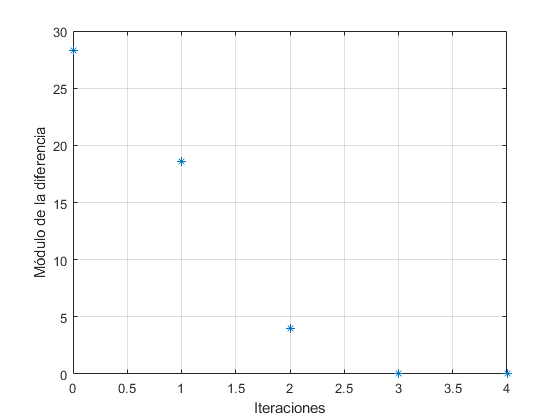

plot(0:length(mod_r_c)-1,mod_r_c,"*")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on

%error final para cada step-size
error=norm(c(:,length(mod_r_c))-r0)

error = 3.4166e-05

c0

c0 = 	1.0e+-4 *

    0.1278
   -0.3168


u

u =      1     1     1     1


num_iteraciones=sum(u)

num_iteraciones = 4